The following livescript calculates the magnetic field strength vectors in the x,y plane surrounding a stripline conductor

using user parameters set by the following inputs. These values are then plotted in a vector field surrounding the rectangular 

stripline. The user can also input a relative x and y position of interest, returning the corresponding magnetic field vector 

components at that point. The result used below is derived from the dissertation: Dmytro, C. (2006) High Frequency Behaviour of Magnetic Thin Film Elements For Microelectronics.

**Properties of stripline:**




I=0.02;
I_in = I / 1000; 
l=300;
h=5;


%useful stripline dimensions:
a = l/2;
b = h/2;


**Position of desired field measurement:**


xstr = "0";
ystr = "2.5";

xpos = str2double(xstr);
ypos = str2double(ystr);

hxpos = longfield(a,b,xpos,ypos,I_in) * 10^9;
hypos = polarfield(a,b,xpos,ypos,I_in) * 10^9;













**Magnetic field strength at (x,y):**


magnitude = sqrt((hypos)^2 + hxpos^2);

fprintf("The longitudinal field component at \n (%.2f,%.2f) is: %.4f A/m", xpos,ypos,hxpos)

The longitudinal field component at 
 (0.00,2.50) is: 32.9797 A/m


fprintf("The polar field component at \n (%.2f,%.2f) is: %.4f A/m", xpos,ypos,hypos)

The polar field component at 
 (0.00,2.50) is: NaN A/m

fprintf("The magnitude of the field strength a \n (%.2f,%.2f) is: %.4f A/m", xpos, ypos, magnitude)

The magnitude of the field strength a 
 (0.00,2.50) is: NaN A/m

**Display parameters:**

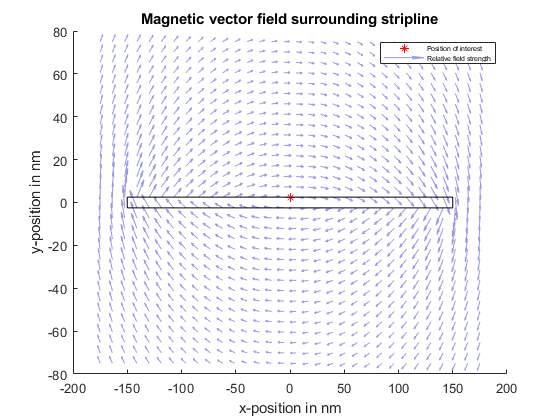



b40 = 40*b;
a1_5 = a*1.5;

arrows = 32;
markersize = 0.5;
xrange1 = 175;
yrange1 = 75;

%evenly distributed points in area of interest in both x and y:

xvec = linspace((-xrange1), xrange1,arrows);
yvec = linspace((-yrange1),yrange1,arrows);

%grid of x and y points for quiver plotting:
[X,Y] = meshgrid(xvec,yvec);


%following code creates a matrix of longitudinal mag-field strength
%by looping through each position vector element in x and y and evaluating
%the Hx field function at that point:

nx = numel(xvec);
hxgrid =zeros(nx);
for i=1:nx
for j=1:nx
    hxi = longfield(a,b,xvec(j),yvec(i),I);
    hxgrid(i,j)=hxi;

end
end

%similar as above but for the polar field component:

ny = numel(yvec);
hygrid =zeros(ny);
for i=1:ny
for j=1:ny
    hyi = polarfield(a,b,xvec(j),yvec(i),I);
    hygrid(i,j)=hyi;

end
end

%As the above field components are given in A/nm, the following converts
%them into the desired units of A/m:

hyfinal = hygrid * 10^9;
hxfinal = hxgrid * 10^9;




scatter(xpos,ypos,'r', "*", "LineWidth", markersize)
hold on

quiver(X,Y,hxfinal,hyfinal,"LineWidth",0.1,"color", [0.6,0.6,0.9])
hold off 

title("Magnetic vector field surrounding stripline")
xlabel("x-position in nm")
ylabel("y-position in nm")
rectangle("Position",[-a -b 2*a 2*b],"LineWidth",0.01, "LineStyle","-")
leg1 = legend("Position of interest","Relative field strength");
set(leg1, "fontsize", 5)

**The following displays the magnetic field strength along one edge of the stripline as a function of x position:**

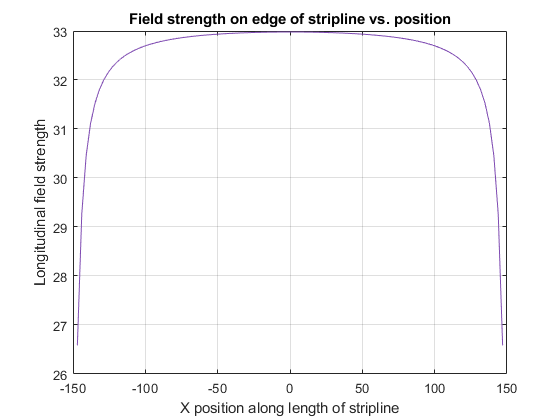


NN = 100;

xpositions = linspace(-a, a, NN);

xfieldstrengths = zeros([NN 1]);
xn = numel(xpositions);

for i=1: xn
    xni = longfield(a,b,xpositions(i), b, I_in);
    xfieldstrengths(i) = xni * 10^9;
end


figure();
plot(xpositions, xfieldstrengths, "color", [0.5,0.3,0.7]);
xlabel("X position along length of stripline");
ylabel("Longitudinal field strength")
title("Field strength on edge of stripline vs. position")
grid on

function [Hx] = longfield(a,b,X,Y,I)
    %a is half of stripline length in nanometers
    %b is half of stripline height in nanometers
    %X is relative x position (centred at 0,0 on the stripline)
    %Y is relative Y position (centred at 0,0 on the stripline)
    %I is current value in amps
    %Returns longitudinal magnetic field component Hx


    p=pi;
    Hx = (-I/(8*p*a*b))* ...
        ((a-X)* ...
        (((1/2)*log(((b-Y)^2 + (a-X)^2)/((-b-Y)^2+(a-X)^2))) ...
        + ((b-Y)/(a-X))*atan((a-X)/(b-Y)) ...
        -((-b-Y)/(a-X))*atan((a-X)/(-b-Y))) ...
        -(-a-X)* ... %potentially +
        ((1/2)*log(((b-Y)^2 + (-a-X)^2)/((-a-X)^2+(-b-Y)^2)) ...
        + ((b-Y)/(-a-X))*atan((-a-X)/(b-Y)) ...
        -((-b-Y)/(-a-X))*atan((-a-X)/(-b-Y))));
end

function [Hy] = polarfield(a,b,X,Y,I)
    %a is half of stripline length in nanometers
    %b is half of stripline height in nanometers
    %X is relative x position (centred at 0,0 on the stripline)
    %Y is relative Y position (centred at 0,0 on the stripline)
    %I is current value in amps
    %Returns polar magnetic field component Hy

    p=pi;
    Hy = (I/(8*p*a*b))* ...
        (((b-Y)* ...
        (((1/2)*log(((b-Y)^2 + (a-X)^2)/((b-Y)^2+(-a-X)^2))) ...
        + ((a-X)/(b-Y))*atan((b-Y)/(a-X)) ...
        -((-a-X)/(b-Y))*atan((b-Y)/(-a-X)))) ...
        -((-b-Y)* ... %potentially +
        ((1/2)*log(((a-X)^2 + (-b-Y)^2)/((-a-X)^2+(-b-Y)^2)) ...
        + ((a-X)/(-b-Y))*atan((-b-Y)/(a-X)) ...
        -((-a-X)/(-b-Y))*atan((-b-Y)/(-a-X)))));
end

